directory = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\Bilder\3 Rechteckige Schilder";
cd(directory);      % Arbeitsverzeichnis setzen

imdsSchilder = imageDatastore(directory, "IncludeSubfolders", true, "LabelSource", "foldernames");

outputFolder = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\Bilder\1_Runde_Schilder\Geschwindigkeitsempfehlungen\Geschwindigkeitsempfehlung 30\Bushaltestelle";

% a= exist(outputFolder, 'dir')
% 
% if a==0;
%     mkdir(outputFolder);
% end
% % 
% Jedes Bild durchlaufen, in Grau umwandeln und speichern
% for i = 1:numel(imdsSchilder.Files)
%     img = imread(imdsSchilder.Files{i});    % Bild laden
%     grayImg = rgb2gray(img);        % In Grau konvertieren
%     [~, filename, ext] = fileparts(imdsSchilder.Files{i}); % Dateiname extrahieren
%     imwrite(grayImg, fullfile(outputFolder, [filename, '_gray', ext])); % Speichern
% end
% imdsSchilderGrau = imageDatastore(outputFolder, "IncludeSubfolders", true, "LabelSource", "foldernames");

Test Dreieckerkennunug

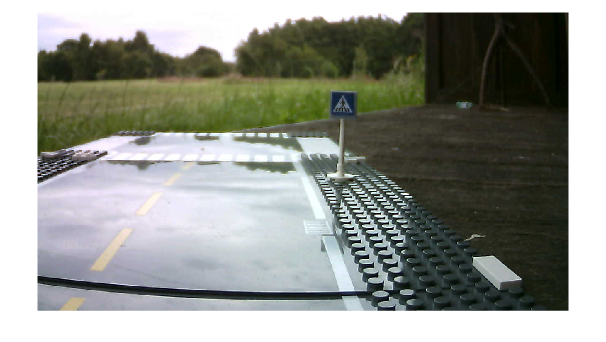


for i = 1:numel(imdsSchilder.Files)
    I = imread(imdsSchilder.Files{i});    % Bild laden
    figure; 
    imshow(I);
    grayImage = rgb2gray(I);
    T = 40;
    C = grayImage > T;
    D = ~C; % Invertierung des Bildes
    
    % Objekte labeln und Eigenschaften analysieren, Achtung hintergrund
    % pixel(Schwarz) werden als Hintergrund nicht als Objekt erkannt

    E = bwlabel(D); % Labeling der Objekte
    imshow(E);
    stats2 = regionprops(E, 'Area', 'Perimeter', 'BoundingBox', 'ConvexHull', 'Extrema');
    output = I;
    % Schleife durch erkannte Regionen
    zaehler = 0;
    % Toleranz für Eckenvereinfachung
    epsilon = 0.06;
    
    for i = 1:length(stats2)
        hull = stats2(i).ConvexHull;
    
        %Nur große genug Objekte weiterverarbeiten
        if stats2(i).Area > 500
            % Vereinfachung des Polygons per Douglas-Peucker, so das nur
            % die Hauptpunkte die das Polygon ausm achen gefunden werden
            simplified = reducepoly(hull, epsilon);
            % Dreiecksprüfung mit Toleranz
            numVertices = size(simplified, 1);
            % gleiPunkte=0;
            % for j = 1:size(simplified, 1)
            %     pt1 = simplified(j, :);
            %         pt2 = simplified(mod(j, size(simplified, 1)) + 1, :);  % zyklischer Vergleich
            %     if isequal(pt1, pt2)
            %         gleiPunkte=1;
            %     end
            % end
            if numVertices ==5
                % Möglicherweise ein Viereck
                output = insertShape(output, 'Polygon', simplified, ...
                    'Color', 'green', 'LineWidth', 3);
            end
        end
    end
    figure; 
    imshow(output);
end